data1 = readtable("sa7035.dat")

data1 = 81×2 table
     Var1       Var2  
    _______    _______

          1          0
    0.99815    0.00017
    0.99265    0.00079
    0.98367    0.00197
    0.97138    0.00375
      0.956    0.00615
    0.93777    0.00913
    0.91689    0.01264
    0.89359    0.01657
    0.86806    0.02082
    0.84049    0.02528
    0.81106    0.02984
    0.77993    0.03442
    0.74727    0.03894
    0.71326    0.04334
     0.6781     0.0476


x_loc = table2array(data1(:,"Var1"))

x_loc =     1.0000
    0.9981
    0.9927
    0.9837
    0.9714
    0.9560
    0.9378
    0.9169
    0.8936
    0.8681


y_loc = table2array(data1(:,"Var2"))

y_loc =          0
    0.0002
    0.0008
    0.0020
    0.0037
    0.0062
    0.0091
    0.0126
    0.0166
    0.0208


data2 = readtable("T2_Re0.278_M0.00_N9.0.csv")

data2 = 146×8 table
       Var1           Var2            Var3                           Var4                          Var5           Var6           Var7         Var8 
    ___________    ___________    ____________    __________________________________________    ___________    ___________    ___________    ______

    {'-2.600,'}    {'0.0214,'}    {'0.00670,'}    {'0.00155,-0.0627,0.7782,0.0052,-1.8911,'}    {'0.0000,'}    {'0.0000,'}    {'0.0000,'}     3.211
    {'-2.500,'}    {'0.0343,'}    {'0.00688,'}    {'0.00153,-0.0631,0.8003,0.0053,-1.7904,'}    {'0.0000,'}    {'0.0000,'}    {'0.0000,'}    2.1046
    {'-2.400,'}    {'0.0463,'}    {'0.00703,'}    {'0.00150,-0.0632,0.8092,0.0055,-1.6910,'}    {'0.0000,'}    {'0.

Airfoil plot

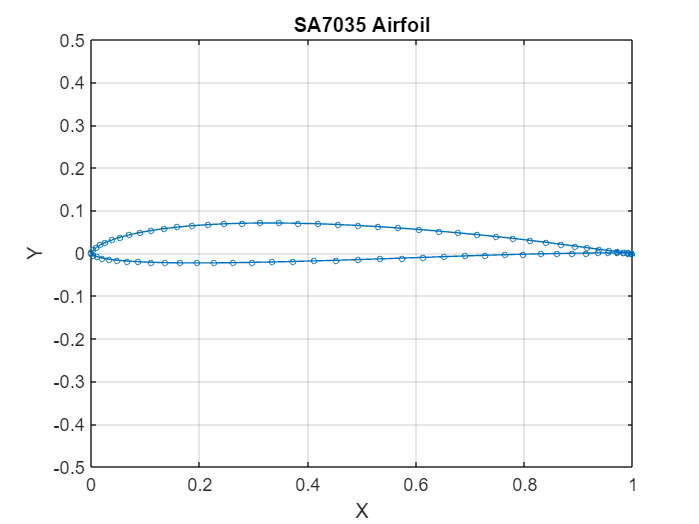

figure()
p = plot(x_loc,y_loc,'-o');
p.MarkerSize = 3;
xlim([0,1])
ylim([-0.5,0.5])
xlabel("X")
ylabel("Y")
title("SA7035 Airfoil")
grid on
saveas(gcf,'Airfoil.png')